# Exercise 1

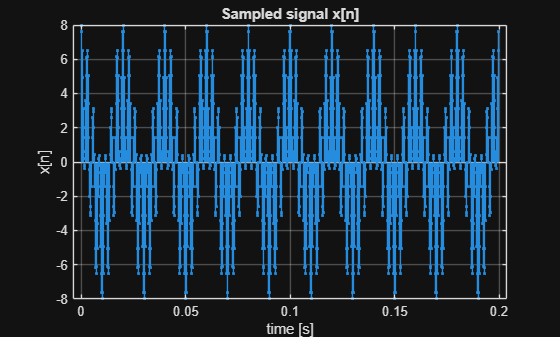


Fs = 5000;              % sampling frequency [Hz]
Ts = 1/Fs;              % sampling period [s]
N  = 1000;              % number of samples

n = 1:N;                % sample indices
t = [0:Ts:(N-1)*Ts];    % 0, Ts, 2Ts, ..., (N-1)Ts Time vector

% Signal Parameters
A1 = 4;  A2 = 4;
F1 = 50; F2 = 350;


%x(t) = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);
% Sampled signal x[n]
x = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);

Df = 1/(N*Ts);
f = [-Fs/2:Df:(Fs/2)-Df];

%a)
% Plot as stem vs time
figure; stem(t, x, '.'); grid on
xlabel('time [s]'); ylabel('x[n]')
title('Sampled signal x[n]')

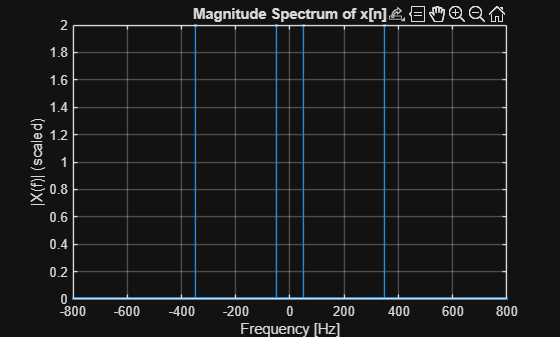


% FFT and frequency axis
X  = fft(x);            % raw FFT
Xc = fftshift(X);       % center zero freq
Xc = Xc / N;            % scale by N

Df = Fs/N;              % frequency spacing [Hz]

% Plot magnitude spectrum
figure;
stem(f, abs(Xc), '.'); grid on
xlabel('Frequency [Hz]');
ylabel('|X(f)| (scaled)');
title('Magnitude Spectrum of x[n]');
xlim([-800 800]);

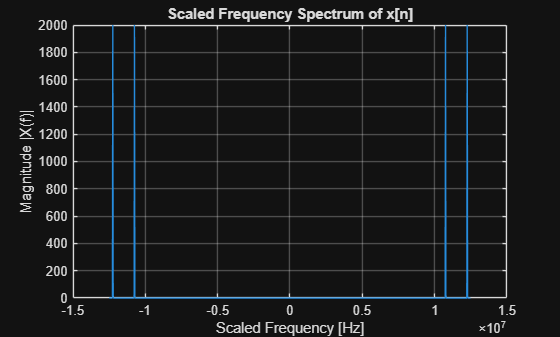



%c)
%plot the scaled (N dependent) absolute value (abs) of the spectrum as
%function of f*Fs.
scaledFreq = f * Fs; % Scale frequency by sampling frequency
figure; plot(scaledFreq, abs(X)); grid on
xlabel('Scaled Frequency [Hz]'); ylabel('Magnitude |X(f)|')
title('Scaled Frequency Spectrum of x[n]')

## Exercise 1-B